# Interactively Read Data from HDF5 File

This example shows how to use the Import Data task to explore the structure of an HDF5 file, import data from the file, and then analyze and visualize the data.

## Explore and Import Data

The HDF5 file included with this example contains a swath of precipitation probability estimates from the NASA Precipitation Processing System (PPS).

Open the Import Data task in the Live Editor by selecting **Task > Import Data** on the **Live Editor** tab. Enter the name of the HDF5 file, `nasa_pps.h5`, in the **File** field. Use the task to explore the structure of the data, including the groups, datasets, and attributes. The file contains a group `S1`, which contains three datasets. The `probabilityOfPrecip` dataset contains estimates of the probability of precipitation at given locations; the `Latitude` and `Longitude` datasets contain the locations of these probability estimates. The attributes of the `probabilityOfPrecip` dataset include `units`, which has value `'percent'`.

Select and import the data and attributes from the three datasets.

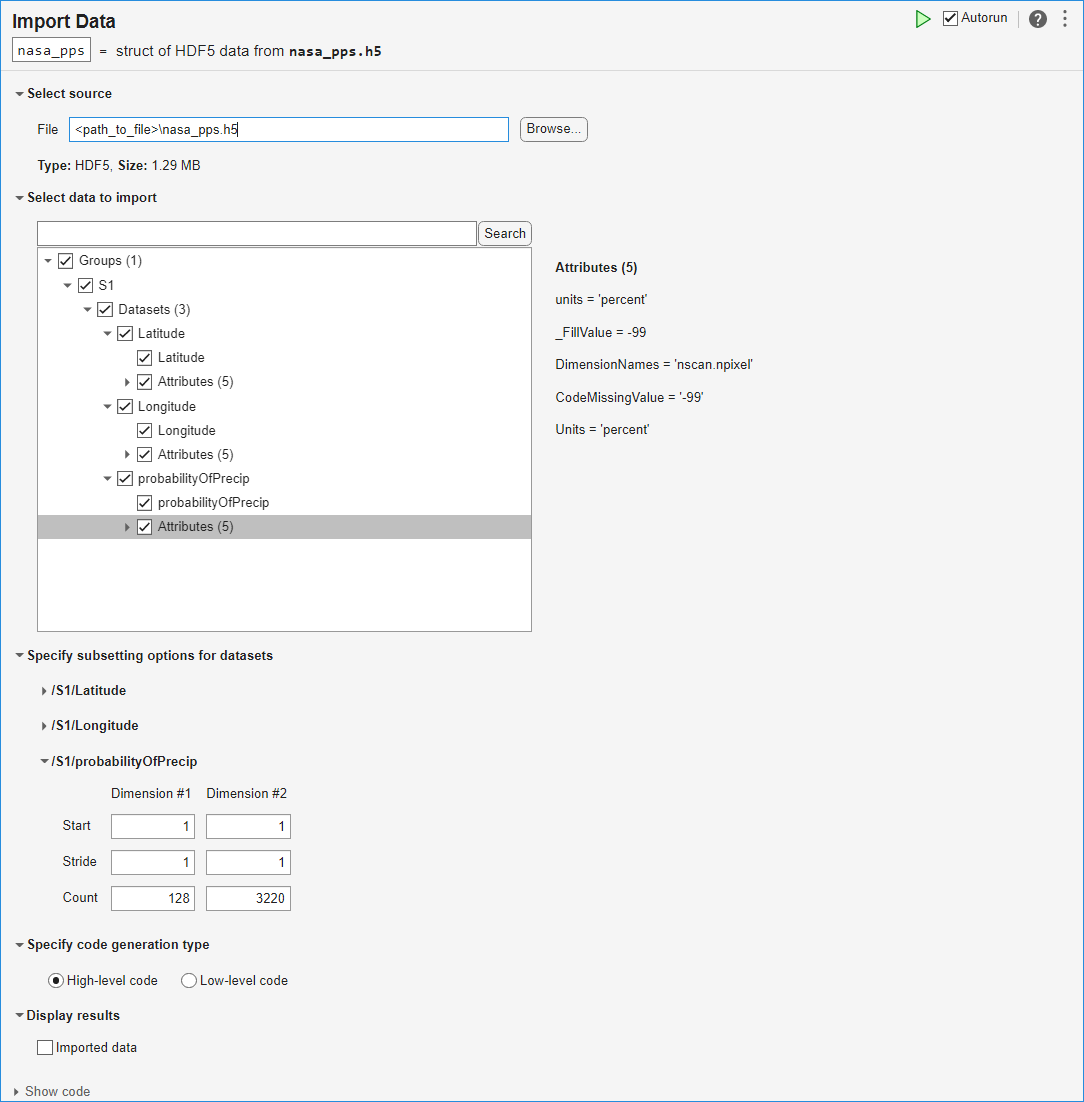

To see the code that this task generates, expand the task display by clicking **Show code** at the bottom of the task parameter area.

% Create a structure to store imported HDF5 data
nasa_pps = struct();

filename = "nasa_pps.h5";

nasa_pps.Groups(1).Name = "S1";

nasa_pps.Groups(1).Datasets(1).Name = "Latitude";
nasa_pps.Groups(1).Datasets(1).Value = h5read(filename, "/S1/Latitude");

nasa_pps.Groups(1).Datasets(2).Name = "Longitude";
nasa_pps.Groups(1).Datasets(2).Value = h5read(filename, "/S1/Longitude");

nasa_pps.Groups(1).Datasets(3).Name = "probabilityOfPrecip";
nasa_pps.Groups(1).Datasets(3).Value = h5read(filename, "/S1/probabilityOfPrecip");

nasa_pps.Groups(1).Datasets(1).Attributes(1).Name = "units";
nasa_pps.Groups(1).Datasets(1).Attributes(1).Value = h5readatt(filename, "/S1/Latitude", "units");

nasa_pps.Groups(1).Datasets(1).Attributes(2).Name = "DimensionNames";
nasa_pps.Groups(1).Datasets(1).Attributes(2).Value = h5readatt(filename, "/S1/Latitude", "DimensionNames");

nasa_pps.Groups(1).Datasets(1).Attributes(3).Name = "Units";
nasa_pps.Groups(1).Datasets(1).Attributes(3).Value = h5readatt(filename, "/S1/Latitude", "Units");

nasa_pps.Groups(1).Datasets(1).Attributes(4).Name = "_FillValue";
nasa_pps.Groups(1).Datasets(1).Attributes(4).Value = h5readatt(filename, "/S1/Latitude", "_FillValue");

nasa_pps.Groups(1).Datasets(1).Attributes(5).Name = "CodeMissingValue";
nasa_pps.Groups(1).Datasets(1).Attributes(5).Value = h5readatt(filename, "/S1/Latitude", "CodeMissingValue");

nasa_pps.Groups(1).Datasets(2).Attributes(1).Name = "units";
nasa_pps.Groups(1).Datasets(2).Attributes(1).Value = h5readatt(filename, "/S1/Longitude", "units");

nasa_pps.Groups(1).Datasets(2).Attributes(2).Name = "DimensionNames";
nasa_pps.Groups(1).Datasets(2).Attributes(2).Value = h5readatt(filename, "/S1/Longitude", "DimensionNames");

nasa_pps.Groups(1).Datasets(2).Attributes(3).Name = "Units";
nasa_pps.Groups(1).Datasets(2).Attributes(3).Value = h5readatt(filename, "/S1/Longitude", "Units");

nasa_pps.Groups(1).Datasets(2).Attributes(4).Name = "_FillValue";
nasa_pps.Groups(1).Datasets(2).Attributes(4).Value = h5readatt(filename, "/S1/Longitude", "_FillValue");

nasa_pps.Groups(1).Datasets(2).Attributes(5).Name = "CodeMissingValue";
nasa_pps.Groups(1).Datasets(2).Attributes(5).Value = h5readatt(filename, "/S1/Longitude", "CodeMissingValue");

nasa_pps.Groups(1).Datasets(3).Attributes(1).Name = "units";
nasa_pps.Groups(1).Datasets(3).Attributes(1).Value = h5readatt(filename, "/S1/probabilityOfPrecip", "units");

nasa_pps.Groups(1).Datasets(3).Attributes(2).Name = "_FillValue";
nasa_pps.Groups(1).Datasets(3).Attributes(2).Value = h5readatt(filename, "/S1/probabilityOfPrecip", "_FillValue");

nasa_pps.Groups(1).Datasets(3).Attributes(3).Name = "DimensionNames";
nasa_pps.Groups(1).Datasets(3).Attributes(3).Value = h5readatt(filename, "/S1/probabilityOfPrecip", "DimensionNames");

nasa_pps.Groups(1).Datasets(3).Attributes(4).Name = "CodeMissingValue";
nasa_pps.Groups(1).Datasets(3).Attributes(4).Value = h5readatt(filename, "/S1/probabilityOfPrecip", "CodeMissingValue");

nasa_pps.Groups(1).Datasets(3).Attributes(5).Name = "Units";
nasa_pps.Groups(1).Datasets(3).Attributes(5).Value = h5readatt(filename, "/S1/probabilityOfPrecip", "Units");

clear filename

## Organize and Prepare Data

Extract data from the three datasets as column vectors using the colon operator (`:`).

lats = nasa_pps.Groups.Datasets(1).Value(:);
lons = nasa_pps.Groups.Datasets(2).Value(:);
probs = nasa_pps.Groups.Datasets(3).Value(:);

Clean up the data in preparation for plotting. Valid indices in these three datasets conform to these conditions:

- The value in `probs` is in the interval [0, 100].

- The value in `lats` is in the interval [–90, 90].

- The value in `lons` is in the interval [–180, 180].

Keep only the values at the valid indices in the three datasets by using logical indexing. This step removes invalid latitude and longitude values as well as invalid percent values for the probability estimates.

isValid = 0<=probs & probs<=100 & abs(lats)<=90 & abs(lons)<=180;

probs = probs(isValid);
lats = lats(isValid);
lons = lons(isValid);

## Plot Data

Create a geographic density plot for the valid data in the datasets. The "warmer" colors represent greater probabilities of precipitation.

g = geodensityplot(lats,lons,probs,FaceColor="interp");
geobasemap grayland
geolimits([-80 80],[-180 -90])
title("Probability of Precipitation vs. Location")
colormap turbo

## Credits

Global precipitation data provided by NASA Precipitation Processing System, from their website at [`https://gpm.nasa.gov/data/directory`](https://gpm.nasa.gov/data/directory).

*Copyright 2023 The MathWorks, Inc.*